clc
clear
s=tf('s');
G=1/(1.516 * s^2);
pole(G)

ans =      0
     0


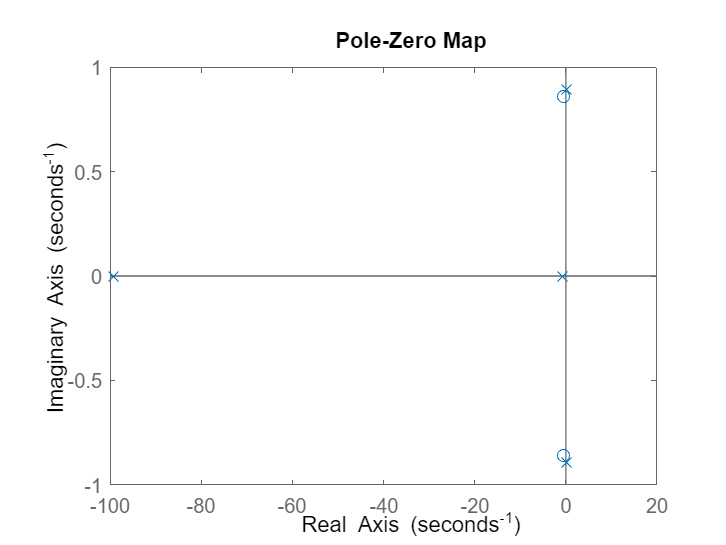

% Kp = 2.7;
% Ki = 0.018;
% Kd = 2.3;
Kp = 5;
Ki = 2;
Kd = 5;
D= Kp+Ki/s+Kd*100/(1+100/s);

sys = feedback(D*G,1);

pzplot(sys)

pole(sys)

ans =  -99.3360 + 0.0000i
  -0.8291 + 0.0000i
   0.0826 + 0.8911i
   0.0826 - 0.8911i


zero(sys)

ans =   -0.5000 + 0.8603i
  -0.5000 - 0.8603i



scale = 40 * pi/180 / 1000

scale = 6.9813e-04

offset = 1500* scale

offset = 1.0472


1000 * scale - offset

ans = -0.3491

2000 * scale - offset

ans = 0.3491